clear all
clf

format longg
Re = 1000;
mu = 0.0010014; %dynamisk viscusitet
rho = 997; %kg/m^3
d = 0.060; %m

U = Re * mu / (rho * d)

U =          0.016740220661986




v_min = 0.00157275

v_min =                 0.00157275


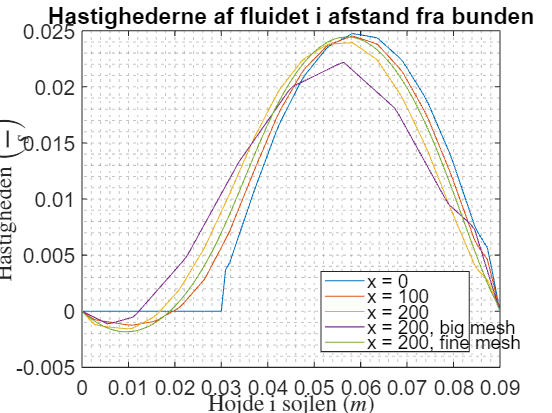


format longg
% Define the filename and sheetname
sheetname = 'Plot Data';

% Import data from Excel file
[numericData1, textData, rawData] = xlsread("Orego.xlsx", sheetname);
Y = numericData1(:,1);
U_Orego = numericData1(:,2);

[numericData2, textData, rawData] = xlsread("Orego+100.xlsx", sheetname);
U_Orego100 = numericData2(:,2);

[numericData3, textData, rawData] = xlsread("Orego+200.xlsx", sheetname);
U_Orego200 = numericData3(:,2);

[numericData4, textData, rawData] = xlsread("2Orego+200.xlsx", sheetname);
U_2Orego200 = numericData4(:,2);

[numericData5, textData, rawData] = xlsread("3Orego+200.xlsx", sheetname);
U_3Orego200 = numericData5(:,2);

plot(Y, U_Orego, DisplayName='x = 0');
hold on
plot(Y, U_Orego100, DisplayName='x = 100');
plot(Y, U_Orego200, DisplayName='x = 200');
plot(Y, U_2Orego200, DisplayName='x = 200, big mesh');
plot(Y, U_3Orego200, DisplayName='x = 200, fine mesh');
title('Hastighederne af fluidet i afstand fra bunden');
xlabel('Hojde i sojlen $(m)$',Interpreter='latex')
ylabel('Hastigheden $\left(\frac{m}{s}\right)$', Interpreter='latex')
grid("minor")
legend('Location', 'best')
hold off


procentvis_afvigelse = mean(abs(U_Orego200(2:end) - U_2Orego200(2:end))./abs(U_Orego200(2:end))) * 100

procentvis_afvigelse =           57.5738916059018



procentvis_afvigelse3 = mean(abs(U_Orego200(2:end) - U_3Orego200(2:end))./abs(U_Orego200(2:end))) * 100

procentvis_afvigelse3 =           25.7110473452308



procentvis_afvigelse3 = mean(abs(U_Orego200(2:end) - U_3Orego200(2:end)./U_3Orego200(2:end))) * 100

procentvis_afvigelse3 =           98.8850420111052


Comparesion enkelt sketch vs full sketch

clf
[numericData_all, textData, rawData] = xlsread("All sketch.xlsx", sheetname);
U_Orego_all = numericData_all(:,2)

U_Orego_all =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


U_Orego_all1 = [];

n = 3; %amount of data sets
n_i = 100; %data set length
i_int = 0;
for j = 1:n
    for i = 1:n_i
        if isnan(U_Orego_all(i))
            break
        else
            U_Orego_all1(i,j) = U_Orego_all(i + i_int);
        end
    end
    i_int = n_i*j + 1*j;
end

U_Orego_all1

U_Orego_all1 =                          0       1.0842021724855e-19                         0
                         0     -0.000262447099663535     -0.000405936863042315
                         0     -0.000522363318452217     -0.000812153425596784
                         0     -0.000754422957469892      -0.00117548227681987
                         0     -0.000814769090240778       -0.0012531842940935
                         0     -0.000874967733137987      -0.00133051178194095
                         0     -0.000934771947312926      -0.00139667545438154
                         0     -0.000993647157256985      -0.00143189028209117
                         0      -0.00105252236720104      -0.00146710510980079
                         0       -0.0011113975771451      -0.00150231993751042


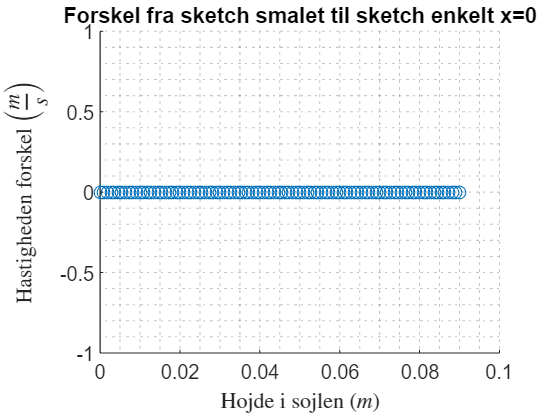


x0_forskel = U_Orego - U_Orego_all1(:,1);
figure(1)
scatter(Y,x0_forskel)
title('Forskel fra sketch smalet til sketch enkelt x=0');
xlabel('Hojde i sojlen $(m)$',Interpreter='latex')
ylabel('Hastigheden forskel $\left(\frac{m}{s}\right)$', Interpreter='latex')
grid("minor")

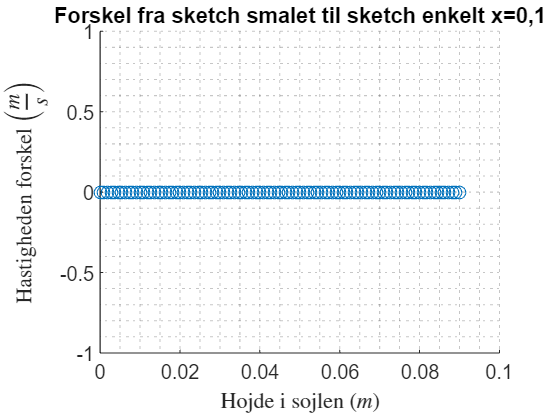


x1_forskel = U_Orego100 - U_Orego_all1(:,2);
figure(2)
scatter(Y,x1_forskel)
title('Forskel fra sketch smalet til sketch enkelt x=0,1');
xlabel('Hojde i sojlen $(m)$',Interpreter='latex')
ylabel('Hastigheden forskel $\left(\frac{m}{s}\right)$', Interpreter='latex')
grid("minor")

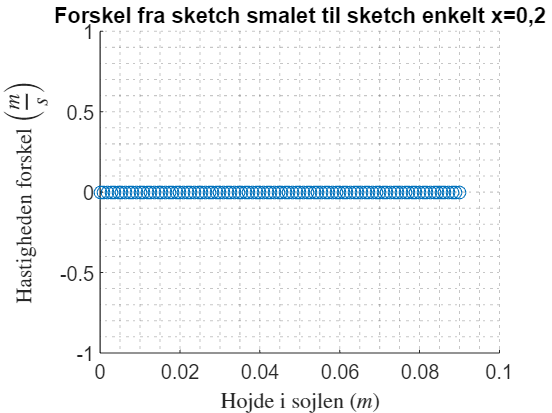



x2_forskel = U_Orego200 - U_Orego_all1(:,3);
figure(3)
scatter(Y,x2_forskel)
title('Forskel fra sketch smalet til sketch enkelt x=0,2');
xlabel('Hojde i sojlen $(m)$',Interpreter='latex')
ylabel('Hastigheden forskel $\left(\frac{m}{s}\right)$', Interpreter='latex')
grid("minor")